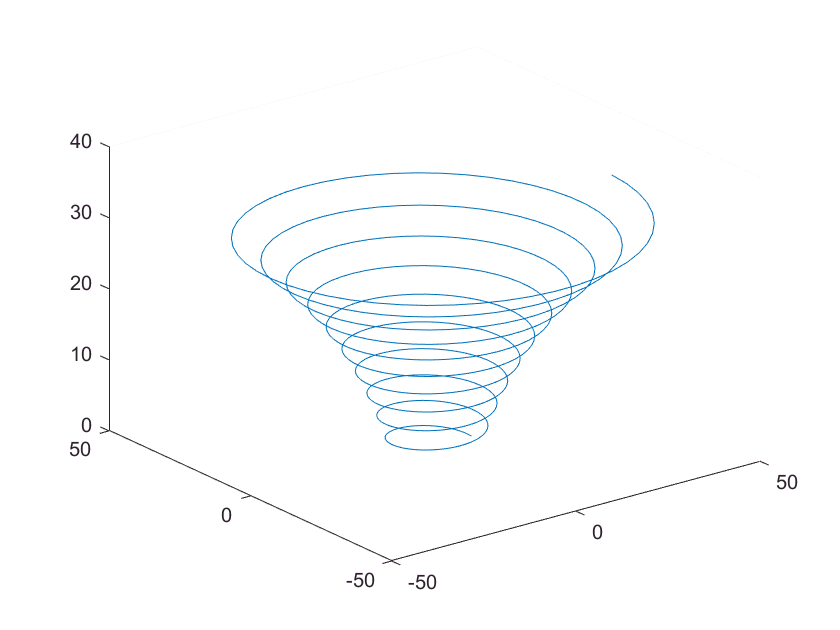

t=0:pi/50:10*pi;
x=10*exp(t/20).*cos(2*t);
y=10*exp(t/20).*sin(2*t);
z=t;
plot3(x,y,z)

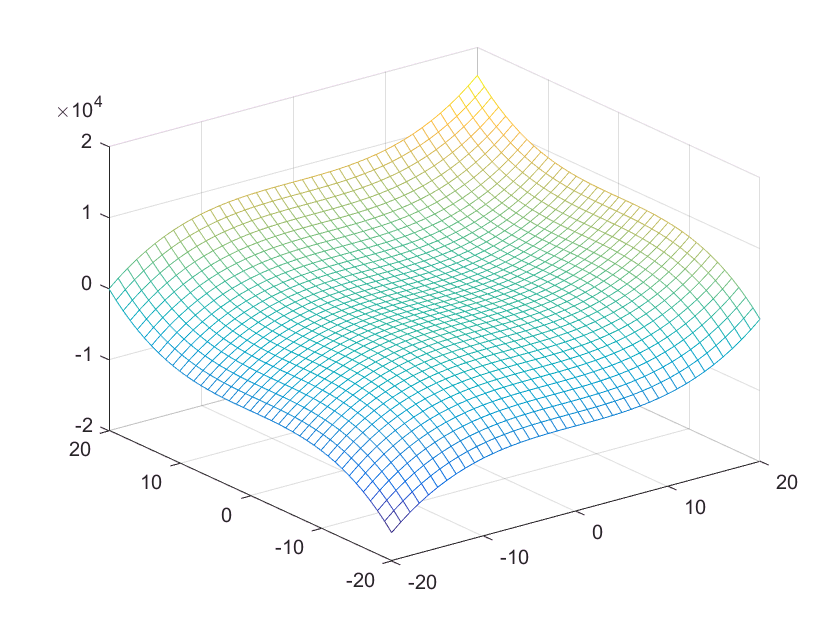

clear
x=-20:20;y=-20:20;
[x,y]=meshgrid(x,y);
z=x.^3+y.^3;
mesh(x,y,z)

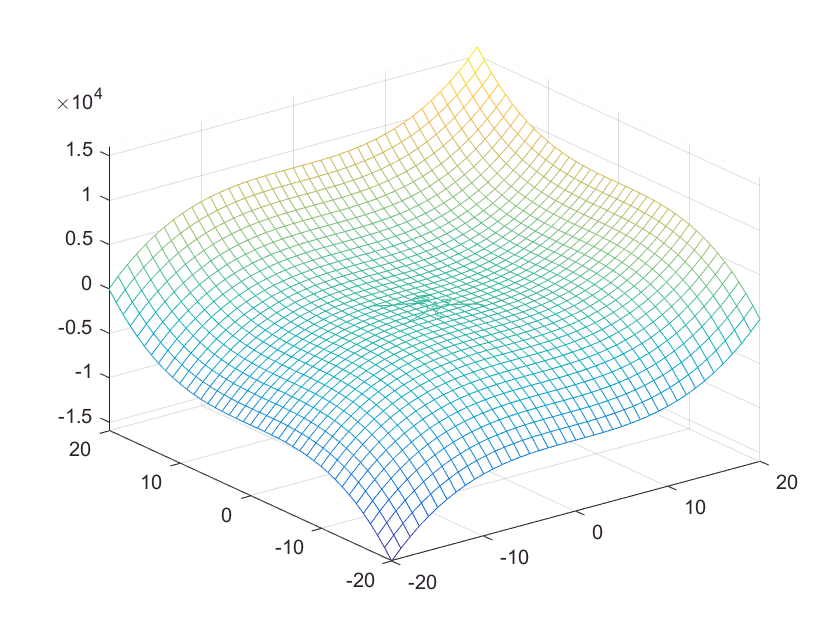

x=-5:0.1:5;y=-3:0.1:3;
[x,y]=meshgrid(x,y);
v=[6 3 0];
z =  3*(1-x).^2.*exp(-(x.^2) - (y+1).^2) ... 
   - 10*(x/5 - x.^3 - y.^5).*exp(-x.^2-y.^2) ... 
   - 1/3*exp(-(x+1).^2 - y.^2) ;
%surf(x,y,z)
hold on
contour3(x,y,z,[0 0])
contour3(x,y,z,[3 3])
contour3(x,y,z,[6 6])

clear
hold off

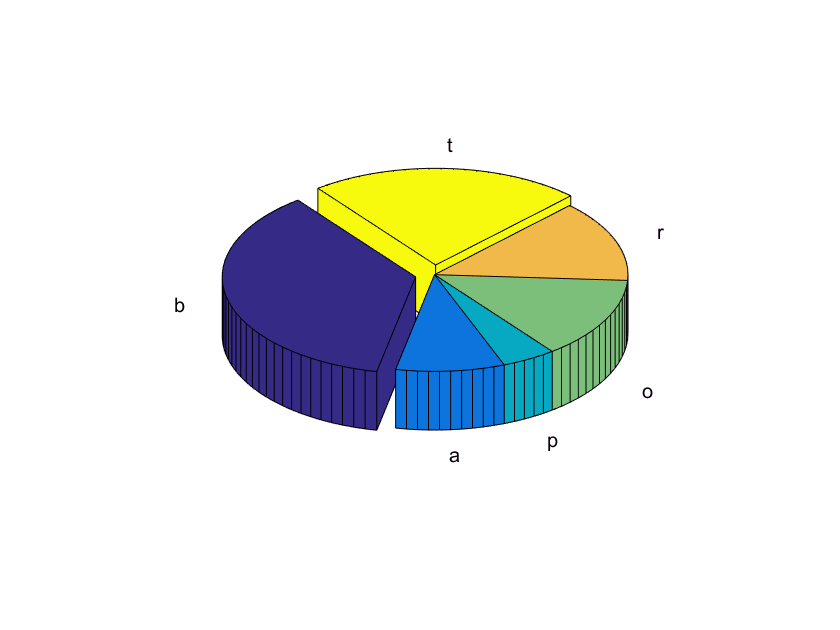

x=[8 2 1 3 3 5];
y=[1 0 0 0 0 1];
z={'b','a','p','o','r','t'};
pie3(x,y,z)

y=@(x)sin(x);

y =     @(x)sin(x)


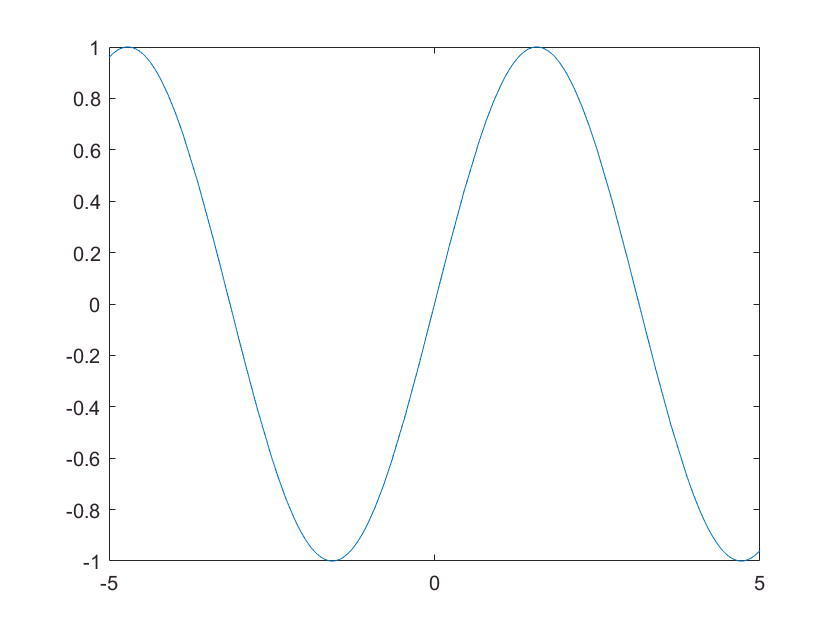

%ezplot(y)
fplot(y)

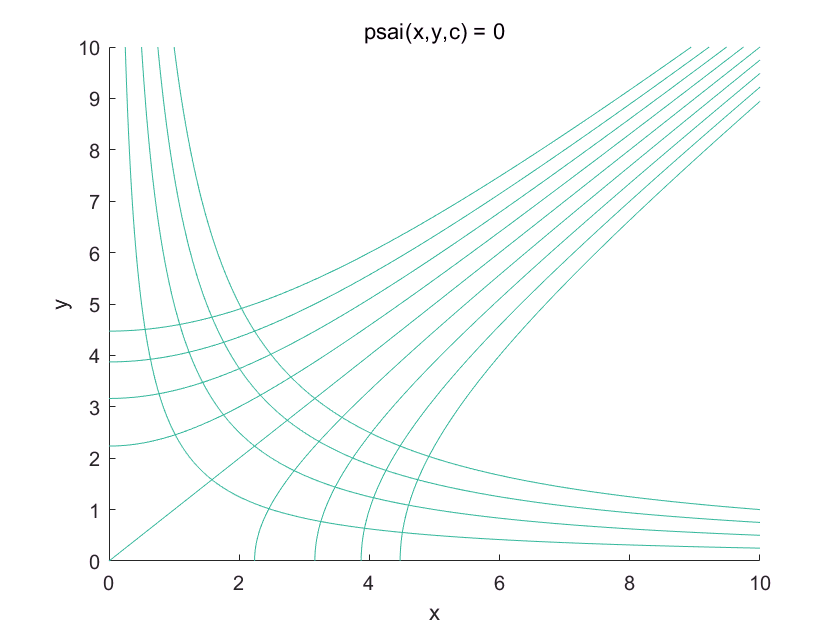

clear
fai=@(x,y,c)x.^2-y.^2+c;
psai=@(x,y,c)2*x.*y+c;
hold on
for c=-20:5:20
   ezplot(@(x,y)fai(x,y,c),[0 10])
   ezplot(@(x,y)psai(x,y,c),[0 10])
end
hold off

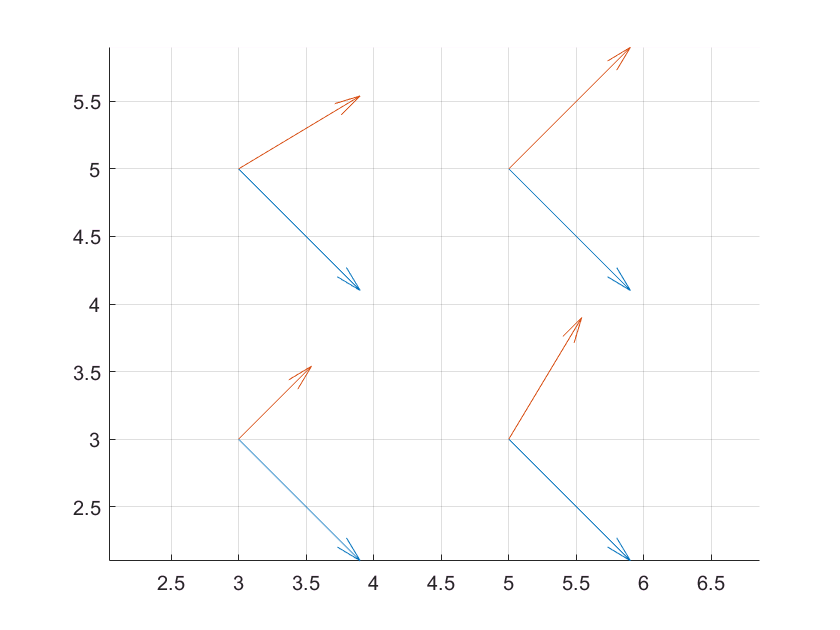

h=2;
x=3:h:5;y=3:h:5;
[x,y]=meshgrid(x,y);
fai=x.^2-y.^2+c;
psai=2*x.*y+c;
[ux,uy]=gradient(fai);
[vx,vy]=gradient(psai);
figure(2)
hold on
quiver(x,y,ux,uy)
quiver(x,y,vx,vy)
axis equal
grid on

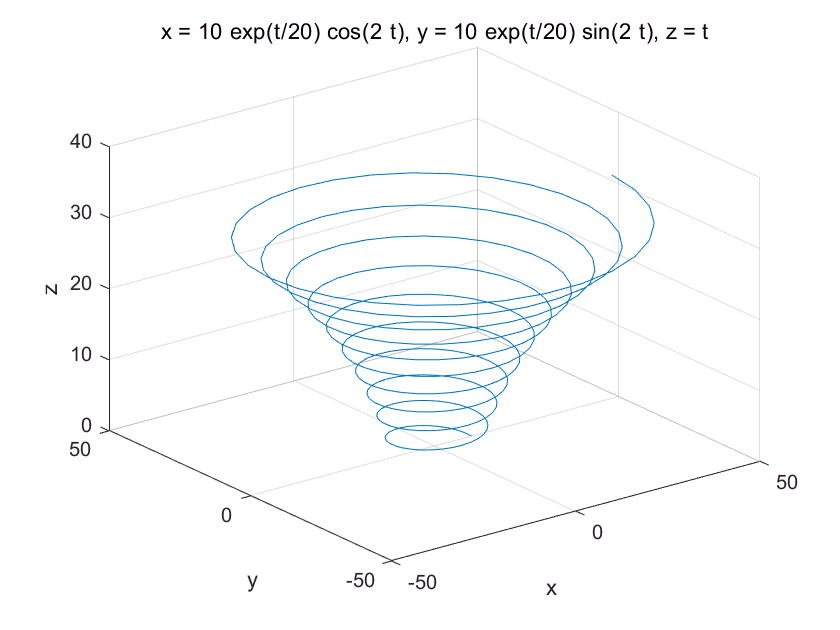

clear
x=@(t)10*exp(t/20).*cos(2*t);
y=@(t)10*exp(t/20).*sin(2*t);
z=@(t)t;
ezplot3(x,y,z,[0 10*pi])

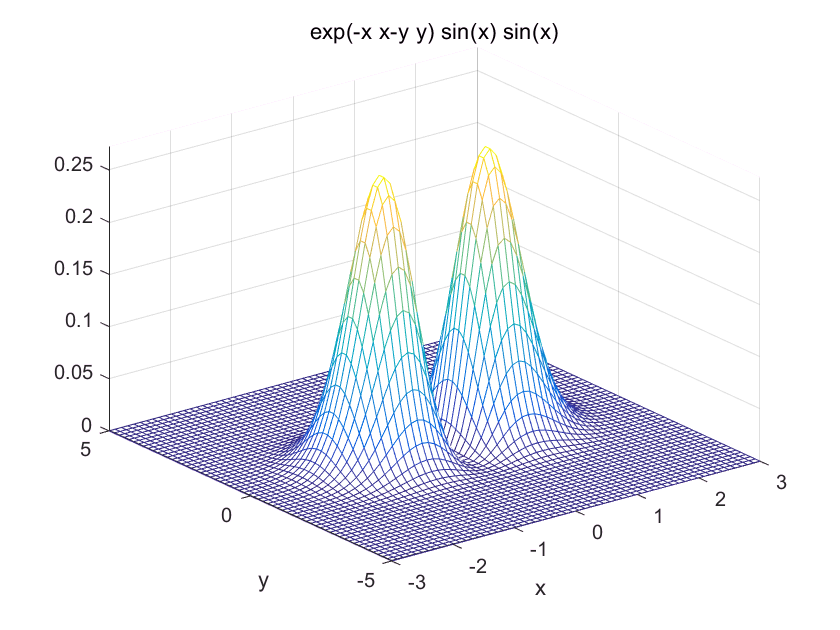

z=@(x,y)exp(-x.*x-y.*y).*sin(x).*sin(x);
ezmesh(z,[-3,3,-5,5])

ezsurf(z,[-3,3,-5,5])

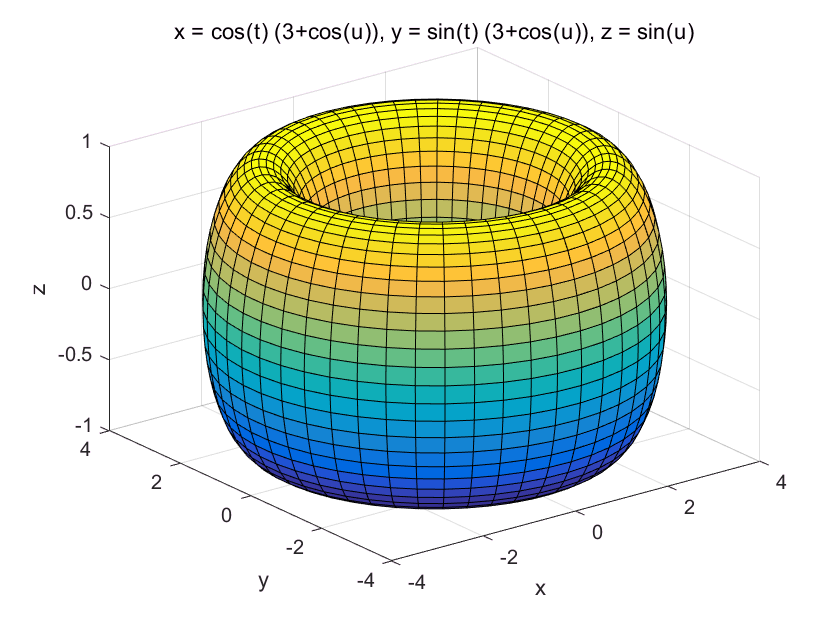

clear
x=@(t,u)cos(t).*(3+cos(u));
y=@(t,u)sin(t).*(3+cos(u));
z=@(t,u)sin(u);
ezsurf(x,y,z,[0,2*pi,0,2*pi])

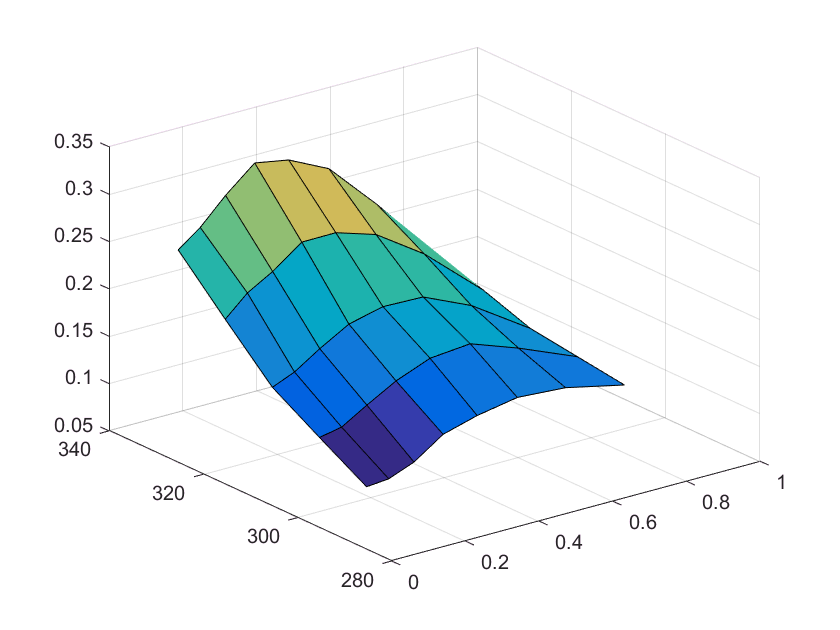

clear
x=[0.1001 0.1602 0.2288 0.3079 0.4003 0.5094 0.6403 0.8002];
y=[293.15 303.15 313.15 323.15 333.15];
[x,y]=meshgrid(x,y);
z=[0.0877 0.1169 0.1470 0.1959 0.2463;0.0898 0.1215 0.1568 0.2174 0.2637;...
    0.1002 0.1375 0.1742 0.2328 0.2903;0.1212 0.1547 0.1918 0.2555 0.3162;...
    0.1313 0.1689 0.2005 0.2557 0.3096;0.1389 0.1727 0.1992 0.2423 0.2889;...
    0.1354 0.1543 0.1764 0.2080 0.2372;0.1214 0.1284 0.1354 0.1530 0.1679];
z=z';
%mesh(x,y,z)
surf(x,y,z)